# ARMA(p, q) process

## ARMA(p, q) model

An ARMA(p,q) process is defined by the difference equation:

        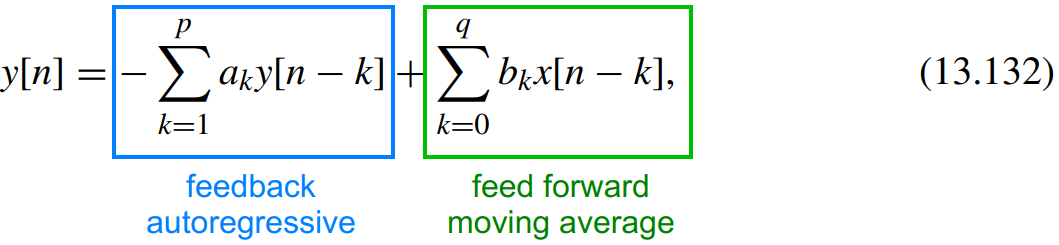

where $x\left\lbrack n\right\rbrack ~\mathrm{WN}\left(0,\sigma_x^2 \right)$

**Lesson:** we always assume that the input to an ARMA(p,q) process is white noise.

### Autocorrelation of ARMA(p,q) process

The autocorrelation of an ARMA(p,q) process is given by:

        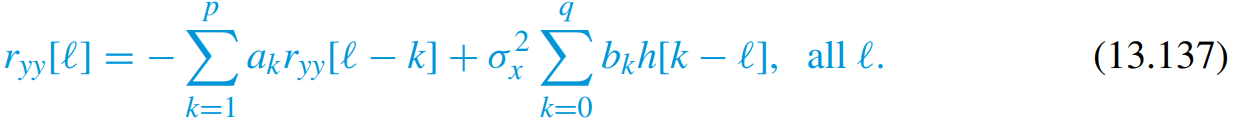

However, we have an issue with this expression. The impulse response $h\left\lbrack n\right\rbrack$ is actually some function of the coefficients $\left\lbrace a_k ,b_k \right\rbrace$.  The issue is that this function is a non-linear. So solving the analytical expression becomes troublesome.

However, if we get rid of the second term by setting $q=0$, the relation becomes linear and we have an AR(p) process:

        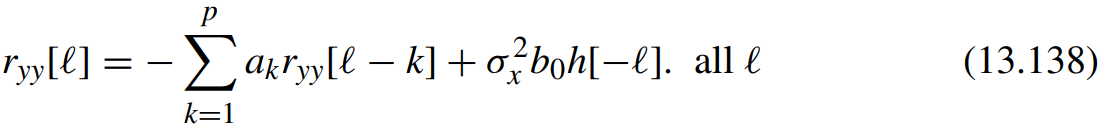

We only consider positive lags $\ell >0$ because $h\left(\ell \right)=0$ for $\ell <0$ i.e., the impulse response does not exists of negative times because it is a causal system.

        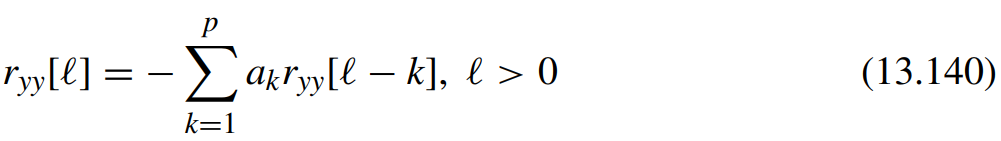

#### ***Quiz:*** why can we choose to set b0=1?

***Quiz:*** why can we choose to set $b_0 =1$?

### AR(p) process

AR(p) model is given by:

        
$$y\left(n\right)=-\sum_{k=1}^p \left\lbrack a_k \;y\left(n-k\right)\right\rbrack +b_0 x\left(n\right)$$


where the input is white noise with zero mean $x\left(n\right)~\mathrm{WN}\left(0,\sigma_x^2 \right)$.

#### Autocorrelation of AR(p) process

The autocorrelation of an ARMA(p,q) process is given by:

        

However, we have an issue with this expression. The impulse response $h\left\lbrack n\right\rbrack$ is actually some function of the coefficients $\left\lbrace a_k ,b_k \right\rbrace$.  The issue is that this function is a non-linear. So solving the analytical expression becomes troublesome.

However, if we get rid of the second term by setting $q=0$, the relation becomes linear and we have an AR(p) process:

        

We only consider positive lags $\ell >0$ because $h\left(\ell \right)=0$ for $\ell <0$ i.e., the impulse response does not exists of negative times because it is a causal system.

        

This is useful because we can use it to find the coefficients $\left\lbrace a_k \right\rbrace$ of an AR(q) model. Given an output signal $y\left(n\right)$, we can compute the autocorrelation $r_{\mathrm{yy}} \left(\ell \right)$ numerically in MATLAB. This means that the expression in Eq. 13.141 becomes a set of $p$ linear equations.

#### Computing AR(p) coefficients from data

For example, if we want to model second-order AR model,$p=2$ we get two equations with two unknowns:

        
$$r_{\mathrm{yy}} \left(1\right)=-a_1 r_{\mathrm{yy}} \left(0\right)-a_2 r_{\mathrm{yy}} \left(-1\right)$$


        
$$r_{\textrm{yy}} \left(2\right)=-a_1 r_{\textrm{yy}} \left(1\right)-a_2 r_{\textrm{yy}} \left(0\right)$$


We can write it into matrix form:

        
$$\left\lbrack \begin{array}{cc}
r_{\textrm{yy}} \left(0\right) & r_{\textrm{yy}} \left(1\right)\\
r_{\textrm{yy}} \left(1\right) & r_{\textrm{yy}} \left(0\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
a_2 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
r_{\textrm{yy}} \left(1\right)\\
r_{\textrm{yy}} \left(2\right)
\end{array}\right\rbrack$$


In the general case, it becomes:

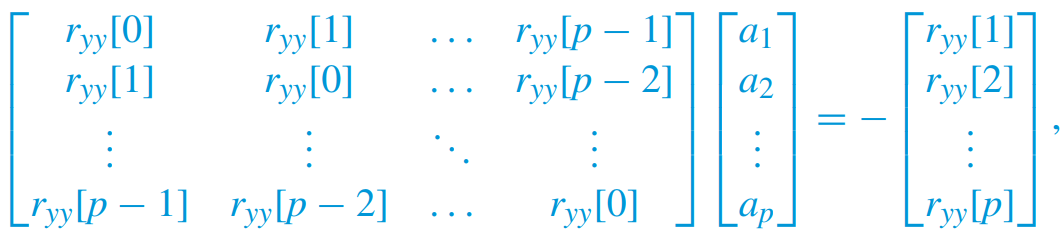

More compactly written as *Yule–Walker equations*:

        

The input noise variance can be compute as follows:

        

We can write a general MATLAB function to find the coefficients $\left\lbrace a_k \right\rbrace$ for any AR(p) model `arfit`.

### MA(q) process

MA(q) process is given by:

        
$$y\left(n\right)=\sum_{k=0}^q b_k \;x\left(n-k\right)$$


This is the ARMA(p, q) model where the feedback part is excluded i.e., all values of $a_k$ is set to zero.

## Problems

### Estimate PSD from an ACRS assuming MA(1) process

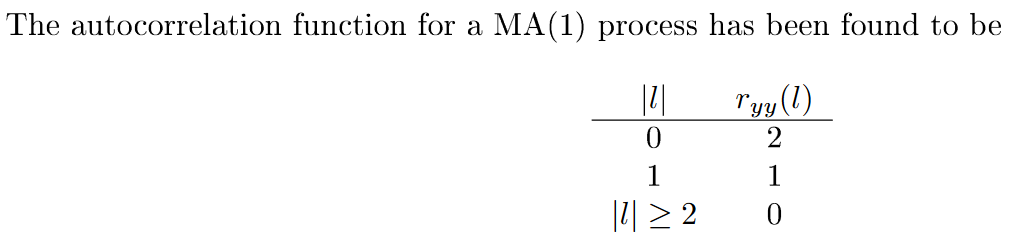

clear variables;

The PSD for an MA(q) process can be computed using Eq. (13.119):

        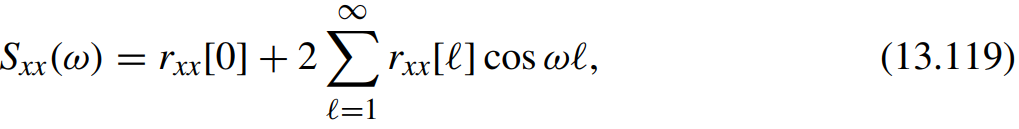

Plugging in our values, we get:

        
$$S_{\textrm{yy}} \left(\omega \right)=2+2\left(1\mathrm{cos}\left(1\omega \right)\right)=2+2\mathrm{cos}\left(\omega \right)$$


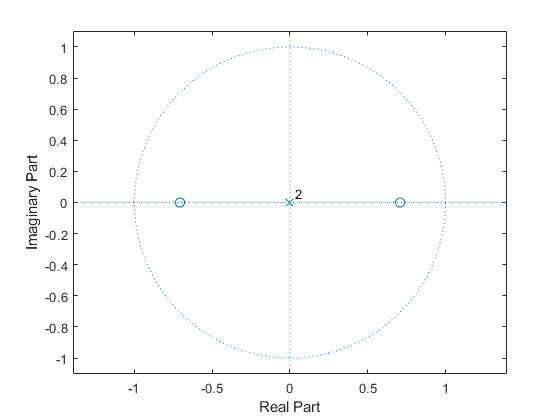

w = 0:0.001:2*pi;

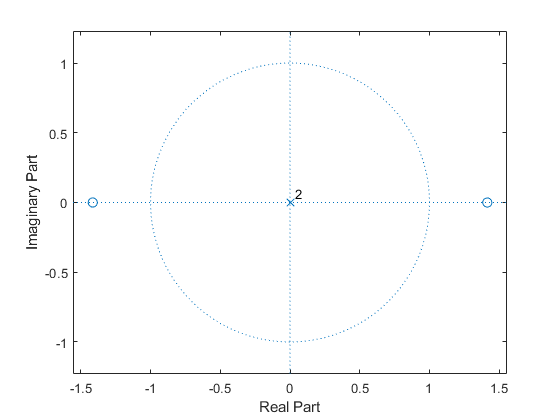

r_xx = [2, 1, 0];
S = r_xx(1);
for l = 2:numel(r_xx)
    S = S + 2 * r_xx(l)*cos(w*(l-1));

end
plot(w, S);
xlabel('Frequency (\omega)');
ylabel('S_{yy}(\omega)');
set(gca,'XTick',0:pi/4:pi) 
set(gca,'XTickLabel',{'0', '\pi/4', '\pi/2', '3\pi/4', '\pi'})
xlim([0, pi])

### Estimate PSD from an ACRS assuming MA(2) process

For a given random process {*x*(*n*)} the autocorrelation has been estimated and is given by:

        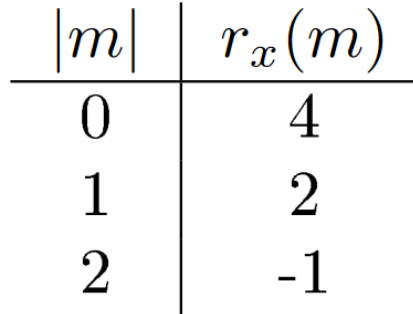

Estimate the power density spectrum under the assumption that {*x*(*n*)} can be described as a *MA*(2) process.  

clear variables;

r_h1 =     -2     0     5     0    -2


The PSD for an MA(q) process can be computed using Eq. (13.119):

        

This gives following expression:

        
$$S_{\mathrm{xx}} \left(\omega \right)=4+2\left(2\mathrm{cos}\left(w\right)+\left(-1\right)\mathrm{cos}\left(2\omega \right)\right)$$


                   
$$=4+4\cos \left(w\right)-2\cos \left(2\omega \right)$$


w=0:0.001:pi;

r_h2 =     -2     0     5     0    -2


r_xx = [4, 2, -1];

S = r_xx(1);
for l = 2:numel(r_xx)
    S = S + 2 * r_xx(l)*cos(w*(l-1));
end

plot(w, S);
xlabel('Frequency (\omega)');
ylabel('S_{yy}(\omega)');
set(gca,'XTick',0:pi/4:pi) 
set(gca,'XTickLabel',{'0', '\pi/4', '\pi/2', '3\pi/4', '\pi'})
xlim([0, pi])

### How to generate a realisation of an AR(3) process?

The signal is disturbed by additive noise from an AR(3) process given by

        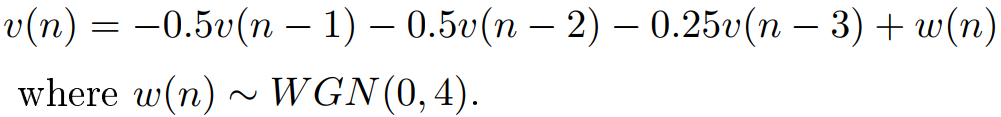

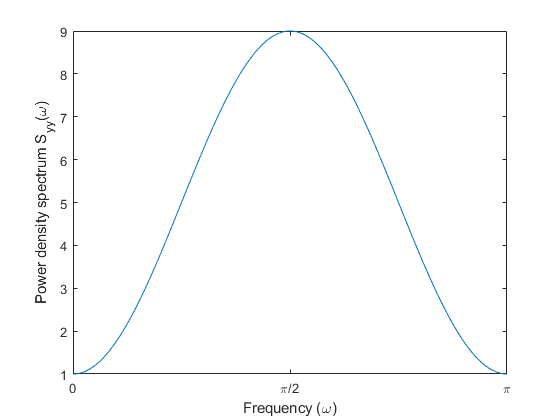

% Generate white noise w[n] with zero mean and variance 4
w_var = 4;
w = sqrt(w_var) * randn(10000, 1);

% Generate noise from an AR(3) process

b = 1;
a = [1, 0.5, 0.5, 0.25];
v = filter(b, a, w);

## ADSI Problem 4.9: MA(q) processes

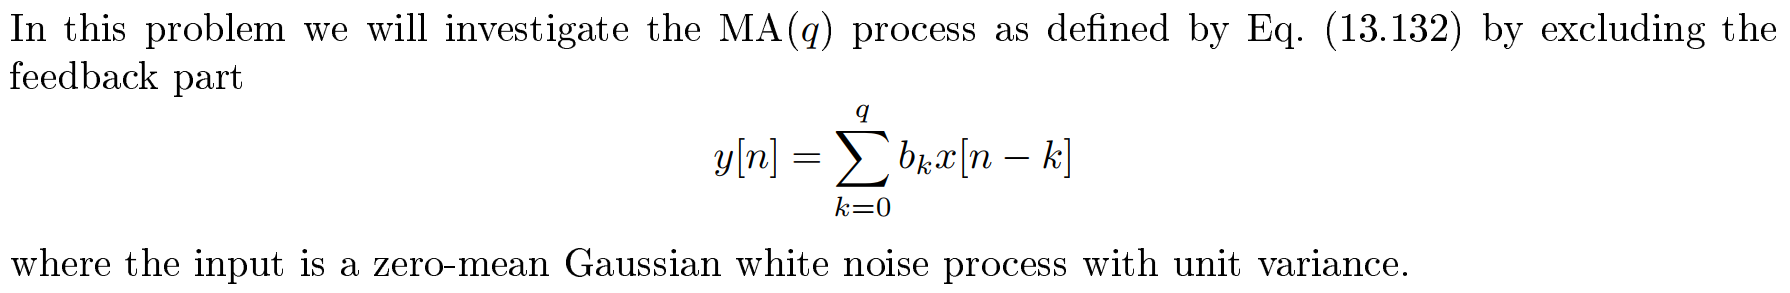

### 1) Full expressions of MA(0) - MA(3) processes

The general $\mathrm{ARMA}\left(p,q\right)$is given by the difference equation:

        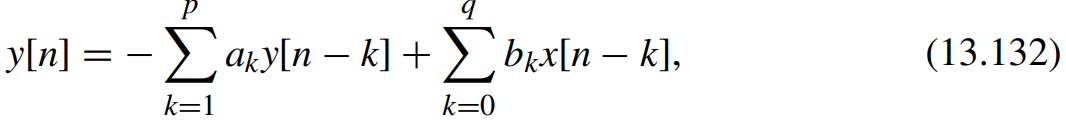

When the feedback part is excluded, all values of $a_k$ is set to zero, we are left with:

        
$$y\left\lbrack n\right\rbrack =\sum_{k=0}^q b_k \;x\left\lbrack n-k\right\rbrack$$


We can write out the full expressions for the difference processes as follows:

        
$$\mathrm{MA}\left(0\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack$$
 

        
$$\mathrm{MA}\left(1\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack$$


        
$$\mathrm{MA}\left(2\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack +b_2 \;x\left\lbrack n-2\right\rbrack$$


        
$$\mathrm{MA}\left(3\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack +b_2 \;x\left\lbrack n-2\right\rbrack +b_3 \;x\left\lbrack n-3\right\rbrack$$


### 2) Calcute the autocorrelation for the MA processes

The autocorrelation function of a random process is defined as:

        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack y\left(n\right)y\left(n-\ell \right)\right\rbrack$$


To compute the autocorrelation for the $\mathrm{MA}\left(0\right)$, just plug its difference equation into this equation:

        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack b_0 \;x\left(n\right)\cdot b_0 \;x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 E\left\lbrack x\left(n\right)\cdot x\left(n-\ell \right)\right\rbrack$$


        
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;r_{\mathrm{xx}} \left(\ell \right)$$
 

The autocorrelation of a white noise signal $w\left(n\right)$ is: $r_{\textrm{ww}} \left(\ell \right)=\sigma_w^2 \delta \left(\ell \right)$ where $\sigma_w^2$ is the signal's variance (see week 6 notes)

We are given that the input signal $x\left(n\right)$ is Gaussian white noise with unit variance.  This means $r_{\textrm{xx}} \left(\ell \right)=\delta \left(\ell \right)$

Therefore, the autocorrelation for MA(0) process is:

        
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;\delta \left(\ell \right)$$
 

The autocorrelation for the $\textrm{MA}\left(1\right)$ process is:

        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack \left(b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack \right)\cdot \left(b_0 \;x\left\lbrack n-\ell \right\rbrack +b_1 \;x\left\lbrack n-\ell -1\right\rbrack \right)\right\rbrack$$


Multiply the two factors:

        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack b_0^2 \;x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack +b_0 b_1 x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack +b_0 b_1 \;x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack +b_1^2 x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$


Rearrange the coefficients:

        
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack b_0^2 \;x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack +b_0 b_1 \left(x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack +x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack \right)+b_1^2 x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$


Split the expectation values and move constants outside $E\left\lbrack \cdot \right\rbrack$

        
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack \right\rbrack +b_0 b_1 \;E\left\lbrack \left(x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack +x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack \right)\right\rbrack +b_1^2 \;E\left\lbrack x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$


Split the expectation value in the second term:

        
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack \right\rbrack +b_0 b_1 \;\left(E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack +E\left\lbrack x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack \right\rbrack \right)+b_1^2 \;E\left\lbrack x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$


Replace expectation values with autocorrelation functions:

        
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;r_{\mathrm{xx}} \left(\ell \right)+b_0 b_1 \;\left(r_{\mathrm{xx}} \left(\ell -1\right)+r_{\mathrm{xx}} \left(\ell +1\right)\right)+b_1^2 \;r_{\mathrm{xx}} \left(\ell \right)$$


Rearrange the terms

        
$$r_{\textrm{yy}} \left(\ell \right)=\left(b_0^2 \;+b_1^2 \right)r_{\textrm{xx}} \left(\ell \right)+b_0 b_1 \;\left(r_{\textrm{xx}} \left(\ell -1\right)+r_{\textrm{xx}} \left(\ell +1\right)\right)$$


As before $r_{\textrm{xx}} \left(\ell \right)=\delta \left(\ell \right)$ because the input signal is a white noise with unit variance. Substitute:

        
$$r_{\textrm{yy}} \left(\ell \right)=\left(b_0^2 \;+b_1^2 \right)\delta \left(\ell \right)+b_0 b_1 \;\left(\delta \left(\ell -1\right)+\delta \left(\ell +1\right)\right)$$


The autocorrelation for an MA(2) process is:

        
$$r_{\mathrm{yy}} \left(\ell \right)=\left(b_0^2 +b_1^2 +b_2^2 \right)\delta \left(\ell \right)+\left(b_0 b_1 +b_1 b_2 \right)\delta \left(\ell +1\right)+\left(b_0 b_1 +b_1 b_2 \right)\delta \left(\ell -1\right)+b_0 b_2 \delta \left(\ell +2\right)+b_0 b_2 \delta \left(\ell -2\right)$$


The autocorrelation for an MA(3) process is:

        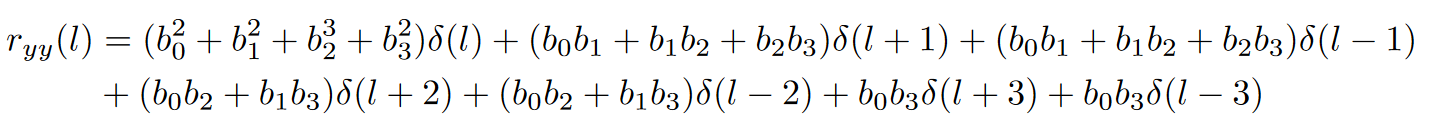

### 3) Calculate power spectral density

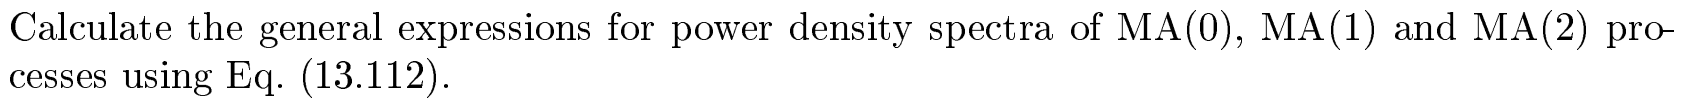

The power spectral density (PSD) is defined as:

        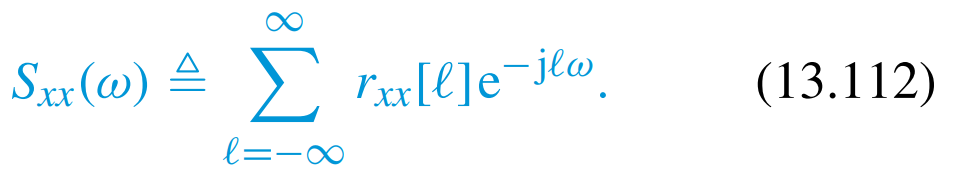

In 2) we found that the autocorrelation for $\mathrm{MA}\left(0\right)$ is $r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;\delta \left(\ell \right)$, so plug it in this PSD formula:

        
$$S_{\textrm{yy}}^{\mathrm{MA}\left(0\right)} \left(\omega \right)=\sum_{\ell =-\infty }^{\infty } r_{\textrm{yy}} \left(\ell \right)e^{-\j \ell \omega } =\sum_{\ell =-\infty }^{\infty } b_0^2 \;\delta \left(\ell \right)e^{-\j \ell \omega }$$


We notice that $r_{\textrm{yy}} \left(\ell \right)$ has non-zero value only when $\ell =0$. Therefore, the terms for when $\ell \not= 0$ are zero. We can, therefore, remove the infinite sum. Since $\delta \left(0\right)=1$and $e^{-\j 0\omega } =1$, we have:

        
$$S_{\textrm{yy}}^{\mathrm{MA}\left(0\right)} \left(\omega \right)=b_0^2 \;\delta \left(0\right)e^{-\j 0\omega } =b_0^2 \cdot 1\cdot 1=b_0^2$$


We do similar computation to find the power density spectrum of MA(1) process. 

In 2) we found that the autocorrelation for MA(1) is:

        
$$r_{\textrm{yy}} \left(\ell \right)=\left(b_0^2 \;+b_1^2 \right)\delta \left(\ell \right)+b_0 b_1 \;\left(\delta \left(\ell -1\right)+\delta \left(\ell +1\right)\right)$$


There are three non-zero values of the autocorrelation function so the infinite sum has only three terms

        
$$S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)=\sum_{\ell =-\infty }^{\infty } \left(\left(b_0^2 \;+b_1^2 \right)\delta \left(\ell \right)+b_0 b_1 \;\left(\delta \left(\ell -1\right)+\delta \left(\ell +1\right)\right)\right)e^{-\j \ell \omega }$$


There are three non-zero values of the autocorrelation function so the infinite sum has only three terms:

- When $\ell =0$:   $\left(b_0^2 \;+b_1^2 \right)\delta \left(0\right)e^{-j\left(0\right)\omega } =\left(b_0^2 \;+b_1^2 \right)\cdot 1\cdot 1=\left(b_0^2 \;+b_1^2 \right)$

- When $\ell =-1$:  $b_0 b_1 \;\delta \left(0\right)e^{-j\left(-1\right)\omega } =b_0 b_1 \;\left(1\right)e^{j\omega } =b_0 b_1 \;e^{j\omega }$

- When $\ell =1$:     $b_0 b_1 \;\delta \left(0\right)e^{-j\left(1\right)\omega } =b_0 b_1 \;\left(1\right)e^{-j\omega } =b_0 b_1 \;e^{-j\omega }$

Therefore, we have:

        
$$S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)=\left(b_0^2 \;+b_1^2 \right)+b_0 b_1 e^{j\omega } +b_0 b_1 e^{-j\omega }$$


        
$$S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)=\left(b_0^2 \;+b_1^2 \right)+b_0 b_1 \left(e^{j\omega } +e^{-j\omega } \right)$$


Since $\mathrm{cos}\left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$ and $2\cdot \mathrm{cos}\left(\theta \right)=e^{j\theta } +e^{-j\theta }$, we write:

        
$$S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)=\left(b_0^2 \;+b_1^2 \right)+2b_0 b_1 \mathrm{cos}\left(\omega \right)$$


In similar fashion, the PSD of $\mathrm{MA}\left(2\right)$ is:

        
$$S_{\textrm{yy}}^{\textrm{MA}\left(2\right)} \left(\omega \right)=\left(b_0^2 \;+b_1^2 +b_2^2 \right)+2\left(b_0 b_1 +b_1 b_2 \right)\cos \left(\omega \right)+2b_0 b_1 \cos \left(2\omega \right)$$


### 4) Plot the power density spectra given coefficients

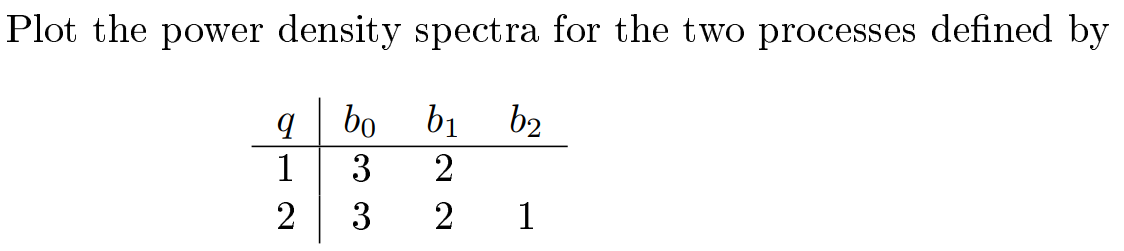

We are given the coefficients for $S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)$and $S_{\textrm{yy}}^{\textrm{MA}\left(2\right)} \left(\omega \right)$. We use results from 3) to plot the power density spectra for the two processes.

        
$$S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)=\left(b_0^2 \;+b_1^2 \right)+2b_0 b_1 \cos \left(\omega \right)$$


        
$$S_{\textrm{yy}}^{\textrm{MA}\left(2\right)} \left(\omega \right)=\left(b_0^2 \;+b_1^2 +b_2^2 \right)+2\left(b_0 b_1 +b_1 b_2 \right)\cos \left(\omega \right)+2b_0 b_1 \cos \left(2\omega \right)$$


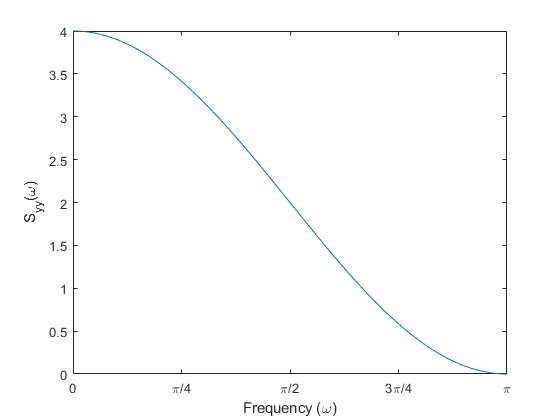

w=0:0.001:2*pi;

% Define the coefficients
b0 = 3; b1 = 2; b2 = 1;

% The power desnity spectrum for the MA(1) process
S1 = (b0^2 + b1^2) + 2*b0*b1*cos(w);
% The power desnity spectrum for the MA(2) process
S2 = (b0^2 + b1^2 + b2^2) + 2*(b0*b1 + b1*b2)*cos(w) + 2*b0*b2*cos(2*w);

plot(w, S1, w, S2);
legend('S_{yy}^{MA(1)}(\omega)','S_{yy}^{MA(2)}(\omega)');
xlabel('Frequency (\omega)');
ylabel('Power density sectra S_{yy}(\omega)');
set(gca,'XTick',0:pi/2:2*pi) 

set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
xlim([0,pi])

## ADSI Problem 4.10: MA(2) processes and phase properties

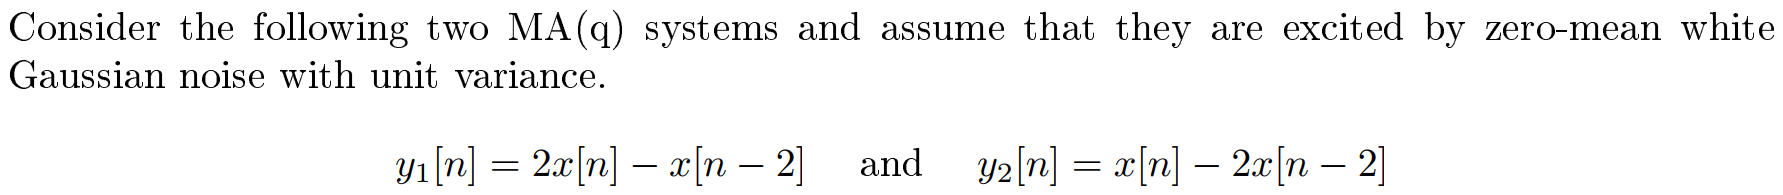

### 1) What is the order q of the processes

The order $q$ of an $\mathrm{MA}\left(q\right)$ process is given by the longest delay, i.e., $x\left\lbrack n-q\right\rbrack$. Therefore, both systems are of order 2.

### 2) Compare the phase properties of the two systems

One important phase property of a system is whether it is invertible. For a MA(q) system, this implies that the all zeros should be inside the unit circle. If all zeros are located within the unit circle, then we have a minimum-phase system.

We can use zero-pole plot in MATLAB:

h1 = [2, 0, -1]; % Impulse response for y1[n]
zplane(h1);

From the zero-pole plot, we observe that all the zeros are within the unit circle. Therefore, we can conclude that the system $y_1 \left\lbrack n\right\rbrack$ is a minimum-phase.

Let us make the zero-plot for the system $y_2 \left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -2x\left\lbrack n-2\right\rbrack$

h2 = [1, 0, -2]; % Impulse response for y2[n]

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

zplane(h2);

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

Since both zeros are outside the unit circle, we can conclude the system $y_2 \left\lbrack n\right\rbrack$ is a maximum-phase system.

### 3) Compute and plot the power density spectra of the two processes 

We are given two MA(q) systems:

        
$$y_1 \left(n\right)=2x\left(n\right)-x\left(n-2\right)$$


        
$$y_2 \left(n\right)=x\left(n\right)-2x\left(n-2\right)$$


where the input is $x\left(n\right)~\mathrm{WGN}\left(0,1\right)$ i.e., white Gaussian noise with unit variance.

We are asked to compute the power density spectra of both systems.

Before we can compute the power density spectrum, we need to find the autocorrelation.

Since we know impulse response, we can use Eq. (13.104) to compute the autocorrelation:

        

where

        

The autocorrelation of white noise is $\sigma_x^2 \delta \left(\ell \right)$ so the ACRS of the input signal:

        
$$r_{\mathrm{xx}} \left(\ell \right)=\sigma_x^2 \delta \left(\ell \right)=1\cdot \delta \left(\ell \right)$$


Since $r_{\mathrm{xx}} \left(\ell \right)=\delta \left(\ell \right)$ then Eq. (13.104) becomes:

        
$$r_{\mathrm{yy}} \left(\ell \right)=r_{\mathrm{hh}} \left(\ell \right)$$


This means that if we compute $r_{\textrm{hh}} \left(\ell \right)$ then we have the autocorrelation.

We can use MATLAB to compute $r_{\mathrm{h1}} \left(\ell \right)$ and $r_{\textrm{h}2} \left(\ell \right)$ :

r_h1 = conv(fliplr(h1), h1)
r_h2 = conv(fliplr(h2), h2)

Now, we have the autocorrelation of both systems. 

        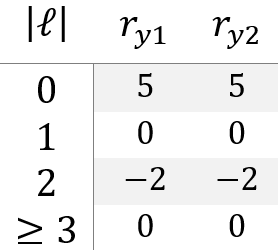

We observe that they are the same. This means that the power spectrum density will be the same.

Whenever we need to compute the PSD based on an autocorrelation sequence, we use Eq. (13.119):

        

Plugging in our values, we get:

        
$$S_{\mathrm{yy}} \left(\omega \right)=5+2\left(0+\left(-2\right)\mathrm{cos}\left(2\omega \right)\right)$$


        
$$S_{\textrm{yy}} \left(\omega \right)=5-4\cos \left(2\omega \right)$$


We can plot it in MATLAB:

w=0:0.001:2*pi;
S_yy = 5 - 4*cos(2*w);
plot(w, S_yy);
xlabel('Frequency (\omega)');
ylabel('Power density spectrum S_{yy}(\omega)');
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
xlim([0, pi])

## ADSI Problem 4.12: MA(q) spectral estimation from autocorrelation

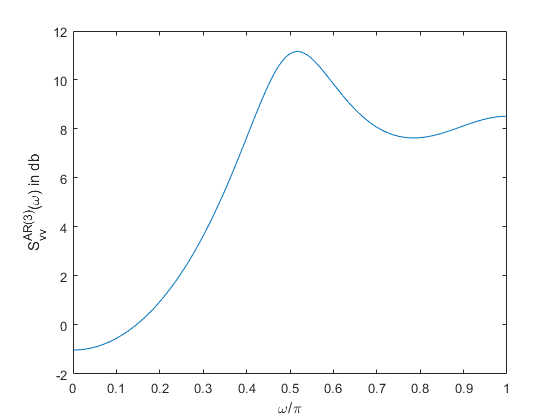

clear variables;

### 1) Compute and plot the power density spectrum

Whenever we need to compute the PSD based on an autocorrelation sequence, we use Eq. (13.119):

        

Plugging in our values, we get:

        
$$S_{\textrm{yy}} \left(\omega \right)=2+2\left(1\mathrm{cos}\left(1\omega \right)\right)=2+2\mathrm{cos}\left(\omega \right)$$


w=0:0.001:2*pi;
S_yy = 2 + 2*cos(w);

a =     0.0340
    0.2232


plot(w, S_yy);
xlabel('Frequency (\omega)');
ylabel('S_{yy}(\omega)');
set(gca,'XTick',0:pi/4:pi) 
set(gca,'XTickLabel',{'0','\pi/4','\pi/2','3\pi/4','\pi'})
xlim([0, pi])

### 2) Calculate the model parameters

We are asked to find $b_0$ and $b_1$ for an MA(1) process given its autocorrelation sequence.

In 1) we found that:

        
$$S_{\textrm{yy}} \left(\omega \right)=2+2\cos \left(\omega \right)$$


In ADSI Problem 4.9, we found that:

        
$$S_{\textrm{yy}}^{\textrm{MA}\left(1\right)} \left(\omega \right)=\left(b_0^2 \;+b_1^2 \right)+2b_0 b_1 \mathrm{cos}\left(\omega \right)$$


This implies that:

        $b_0^2 \;+b_1^2 =2$  and   $b_0 b_1 =1$

Rewriting the second equation:

        
$$b_0 =\frac{1}{b_1 }$$


We can substitute in the first equation:

        
$$\frac{1}{b_1^2 }\;+b_1^2 =2$$


From the equation above, we see that $b_1 =\pm 1$. We turn our attention the second equation:

        $b_0 =1$ if $b_1 =1$

        $b_0 =-1$ if $b_1 =-1$

So the model parameters are $b_0 =1,b_1 =1$ or $b_0 =-1,b_1 =-1$.

% Verify in MATLAB
syms b0 b1
solution = solve([b0^2 + b1^2 == 2, b0*b1 == 1], [b0, b1]);
solution.b0
solution.b1

### Plot the power density spectrum an AR(3) process

clear variables;

Here is an AR(3) process plus some white Gaussian noise:

        

We can determine the Power Density Spectrum of an ARMA(p,q) process is given by

        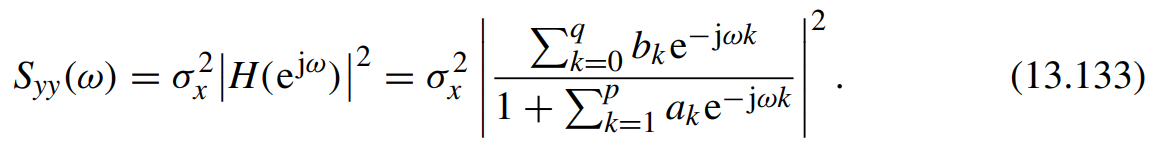

The power spectrum of an AR(p) process is given by:

        
$$S_{\mathrm{yy}} \left(\omega \right)=\sigma_x^2 {\left|\frac{1}{1+\sum_{k=1}^p a_k e^{-j\omega k} }\right|}^2$$


For this problem, we have:

        
$$S_{\mathrm{vv}} \left(\omega \right)=4{\left|\frac{1}{1+0\ldotp 5e^{-j\omega } +0\ldotp 5e^{-\mathrm{j2}\omega } +0\ldotp 25e^{-\mathrm{j3}\omega } }\right|}^2$$


The algorithm is as follows:

- Use the coefficents $\left\lbrace a_1 ,a_2 ,\cdots ,a_p \right\rbrace$ for the$\mathrm{AR}\left(p\right)$ model, 

- Compute the transfer function for the $\mathrm{AR}\left(p\right)$ by computing the sum and finding its reciprocal

- Compute the conjugate of the transfer function: ${\left|H\left(e^{j\omega } \right)\right|}^2$

- Multiply it with the variance $\sigma_x^2$

The algorithm is implemented in the functions `ar2psd()` function:

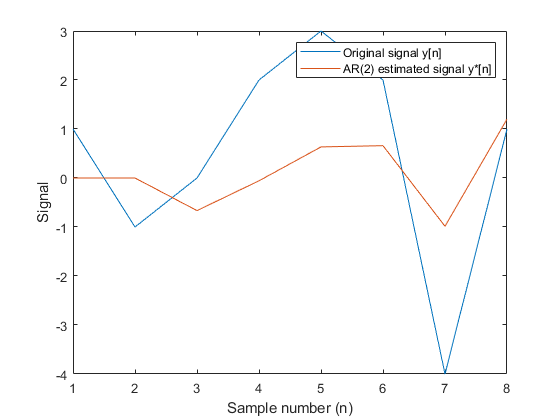

N = 256;

a = [0.5, 0.5, 0.25]; % The coefficients of the AR(3) model
w_var = 4; % The variance of white noise
[S_vv, w] = ar2psd(a, w_var, N); % Compute the PSD of AR(3) model

plot(w/pi, pow2db(S_vv))
xlabel('\omega/\pi')

ylabel('S_{vv}^{AR(3)}(\omega) in db')

## ADSI Problem 6.2: Autocorrelation expression for an AR(1) process (proof)

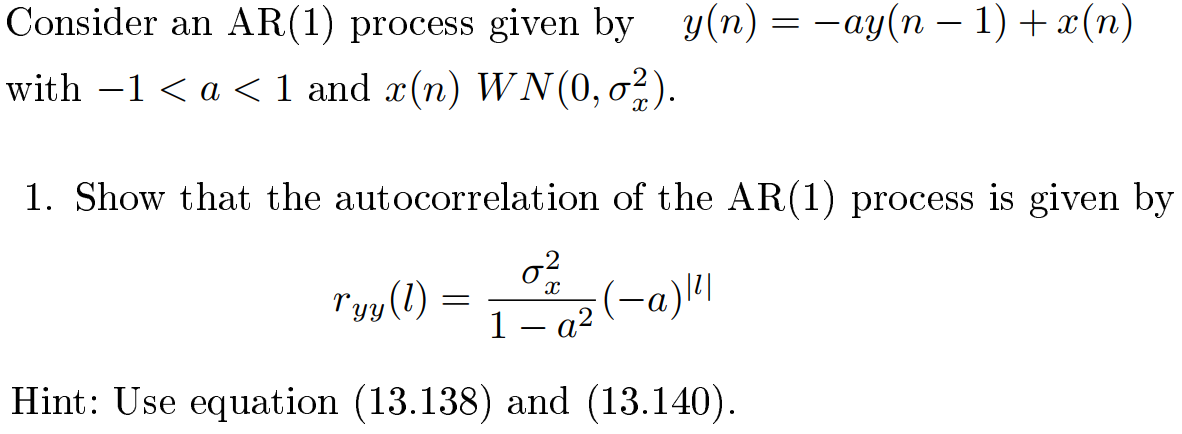

The autocorrelation of an AR(p) process is given by Eq. 13.138:

        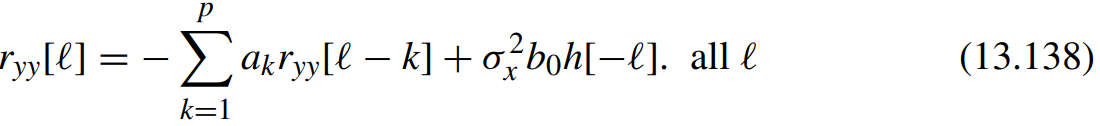

where $h\left\lbrack n\right\rbrack$ is the impulse response of an all-pole system.

The impulse response of an all-pole system satisfies the difference equation

        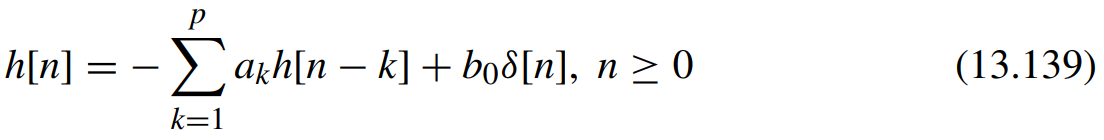

where $h\left\lbrack n\right\rbrack =0$ for $n<0$

Equation 13.138 is an general expression for all $\ell$. However, since $h\left\lbrack \ell \right\rbrack =0$ for negative values of $\ell$ then we know that $h\left\lbrack -\ell \right\rbrack =0$. Therefore, Eq. 13.138 can be reduced to:

        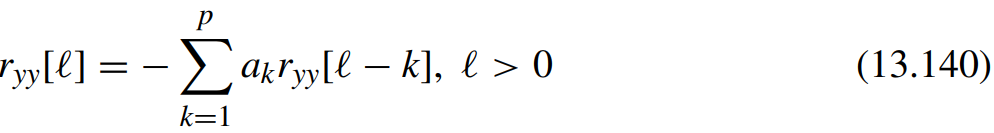

For an AR(1) process, Eq. 13.138 simplifies to:

        $r_{\mathrm{yy}} \left\lbrack \ell \right\rbrack =-a_1 r_{\mathrm{yy}} \left\lbrack \ell -1\right\rbrack +\sigma_x^2 b_0 h\left\lbrack -\ell \right\rbrack$ for all $\ell$

For an AR(1) process, Eq. 13.140 simplifies to:

        $r_{\mathrm{yy}} \left\lbrack \ell \right\rbrack =-a_1 r_{\mathrm{yy}} \left\lbrack \ell -1\right\rbrack$ for $\ell >0$

Setting $\ell =0$ in the first equation, we get:

        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack -1\right\rbrack +\sigma_x^2 b_0 h\left\lbrack 0\right\rbrack$$


The book says that $h\left\lbrack 0\right\rbrack =b_0 =1$ so we are left with:

        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack -1\right\rbrack +\sigma_x^2$$


We can use the symmetry property of autocorrelation function i.e., $r_{\textrm{yy}} \left\lbrack -\ell \right\rbrack =r_{\textrm{yy}} \left\lbrack \ell \right\rbrack$:

        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 1\right\rbrack +\sigma_x^2$$


To find an expression for $r_{\mathrm{yy}} \left\lbrack 1\right\rbrack$, we set $\ell =1$ in the second equation:

        
$$r_{\textrm{yy}} \left\lbrack 1\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 0\right\rbrack$$


We insert the second equation into the first equation:

        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =-a_1 \left(-a_1 r_{\textrm{yy}} \left\lbrack 0\right\rbrack \right)+\sigma_x^2$$


        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =a_1^2 r_{\mathrm{yy}} \left\lbrack 0\right\rbrack +\sigma_x^2$$


        
$$\sigma_x^2 =r_{\textrm{yy}} \left\lbrack 0\right\rbrack -a_1^2 r_{\textrm{yy}} \left\lbrack 0\right\rbrack$$


        
$$\sigma_x^2 =r_{\textrm{yy}} \left\lbrack 0\right\rbrack \left(1-a_1^2 \right)$$


        
$$r_{\textrm{yy}} \left\lbrack 0\right\rbrack =\frac{\sigma_x^2 }{1-a_1^2 }$$


Now, we need to find an expression for $\ell >0$. We can do this by using the second equation.

First, we set $\ell =1$ in the second equation:

        
$$r_{\textrm{yy}} \left\lbrack 1\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 0\right\rbrack \Leftrightarrow -a_1 \frac{\sigma_x^2 }{1-a_1^2 }$$


        
$$r_{\textrm{yy}} \left\lbrack 2\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 1\right\rbrack \Leftrightarrow -a_1 \left(-a_1 \frac{\sigma_x^2 }{1-a_1^2 }\right)\Leftrightarrow {\left(-a_1 \right)}^2 \frac{\sigma_x^2 }{1-a_1^2 }$$


        
$$r_{\textrm{yy}} \left\lbrack 3\right\rbrack =-a_1 r_{\textrm{yy}} \left\lbrack 2\right\rbrack \Leftrightarrow -a_1 \left({\left(-a_1 \right)}^2 \frac{\sigma_x^2 }{1-a_1^2 }\right)\Leftrightarrow {\left(-a_1 \right)}^3 \frac{\sigma_x^2 }{1-a_1^2 }$$


This means that in general, we have:

        
$$r_{\textrm{yy}} \left\lbrack \ell \right\rbrack ={\left(-a_1 \right)}^{\ell } \frac{\sigma_x^2 }{1-a_1^2 }$$


If we apply the symmetric property of the autocorrelation, we get:

        
$$r_{\textrm{yy}} \left\lbrack \ell \right\rbrack ={\left(-a_1 \right)}^{\left|\ell \right|} \frac{\sigma_x^2 }{1-a_1^2 }$$


## Problems True/False

### The autocorrelation function of an AR(*p*) is equal to zero for lags larger than *p*.  

An AR(*p*) process is effectively white noise sent through an IIR filter. This implies that a correlation will exist between infinitely distant samples. While the autocorrelation function can be zero for any lag it is generally different from zero for almost all lags. 

Note though, that for all AR(2) processes encountered in real life, the autocorrelation values gets exponentially close to zero for large lags.

### Quiz: Is the comb filter an MA(1) proces?

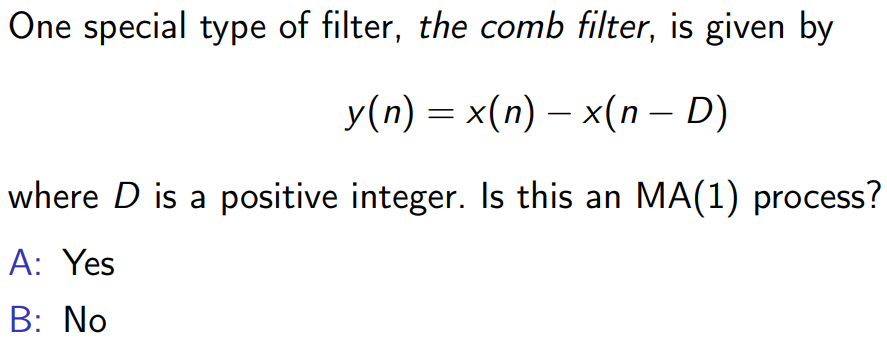

The answer is no!

### Quiz: Determine kind of model based on the inpulse response

The impulse response for a specific ARMA(*p,**q*) model is shown below.

What kind of model is shown?

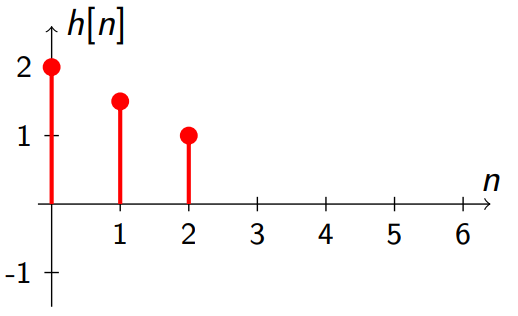

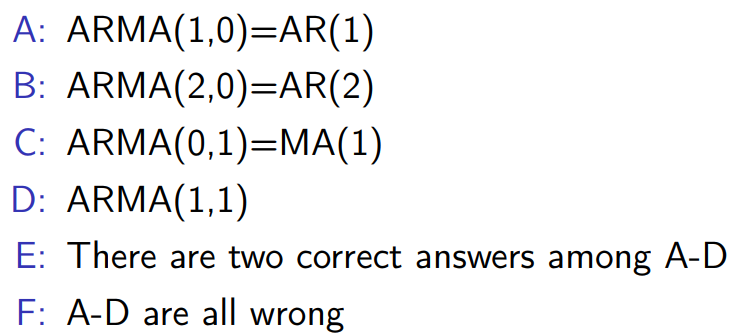

The correct answer is F.

The autoregressive part of the ARMA(p,q) model has infinite impulse response. What we see in the figure is finite impulse response with three elements. Therefore, it must be an MA(q) model.

Since the figure shows three filter coefficients, the system must be an MA(2) process.

If the figure indicated infinite filter coefficients, we could not have determined the order of the model. In this case, it would be either an autoregressive model or a high-order MA(q) model.

## [✔] Exam 2012, Problem 2: Construct an AR(2) model using a signal from a random process

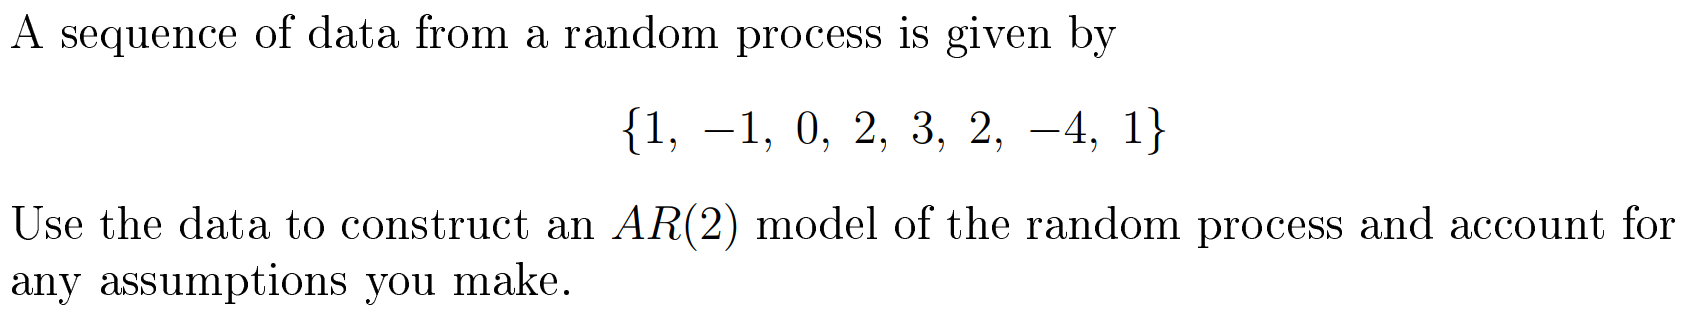

We assume that the given sequence is the output of a process whose input was white Gaussian noise with zero mean and unit variance:

        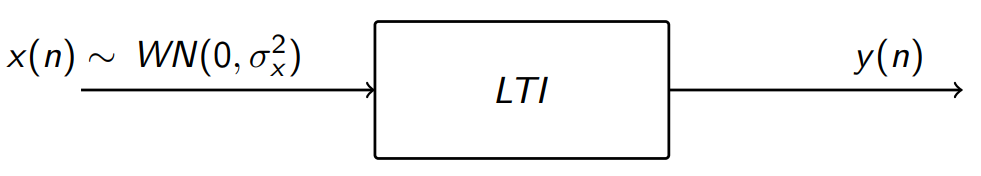

Given the input is white noise with zero mean $x\left(n\right)~\mathrm{WN}\left(0,\sigma_x^2 \right)$, the autocorrelation of an AR(q) model is given by Eq. 13.141:

        
$$r_{\mathrm{yy}} \left(\ell \right)=-\sum_{k=1}^p a_k r_{\mathrm{yy}} \left(\ell -k\right),\;\;\;\ell >0$$
 

This is useful because we can use it to find the coefficients $\left\lbrace a_k \right\rbrace$ of an AR(q) model. Given an output signal $y\left(n\right)$, we can compute the autocorrelation $r_{\mathrm{yy}} \left(\ell \right)$ numerically in MATLAB. This means that the expression in Eq. 13.141 becomes a set of $p$ linear equations.

For a second-order $p=2$ AR model, we get two equations with two unknowns:

        
$$r_{\mathrm{yy}} \left(1\right)=-a_1 r_{\mathrm{yy}} \left(0\right)-a_2 r_{\mathrm{yy}} \left(-1\right)$$


        
$$r_{\textrm{yy}} \left(2\right)=-a_1 r_{\textrm{yy}} \left(1\right)-a_2 r_{\textrm{yy}} \left(0\right)$$


We can write it into matrix form:

        
$$\left\lbrack \begin{array}{cc}
r_{\textrm{yy}} \left(0\right) & r_{\textrm{yy}} \left(1\right)\\
r_{\textrm{yy}} \left(1\right) & r_{\textrm{yy}} \left(0\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
a_2 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
r_{\textrm{yy}} \left(1\right)\\
r_{\textrm{yy}} \left(2\right)
\end{array}\right\rbrack$$


Solving it will give us the AR(2) model coefficients $\left\lbrace a_1 ,a_2 \right\rbrace$.

This is implemented in the arfit() function:

y = [1, -1, 0, 2, 3, 2, -4, 1];
[a, ~] = arfit(y, 2)

The coefficients for the AR(2) model is; $a_1 =0\ldotp 0340$ and $a_2 =0\ldotp 2232$.

        
$$y\left(n\right)=-\left\lbrack 0\ldotp 0340y\left(n-1\right)+0\ldotp 2232y\left(n-2\right)\right\rbrack +b_0 x\left(n\right)$$


We can plot the signal and the estimated AR(2) signal:

N = 8;

% Generate the input

a =    -1.5604
    0.8114


v = 0.9922

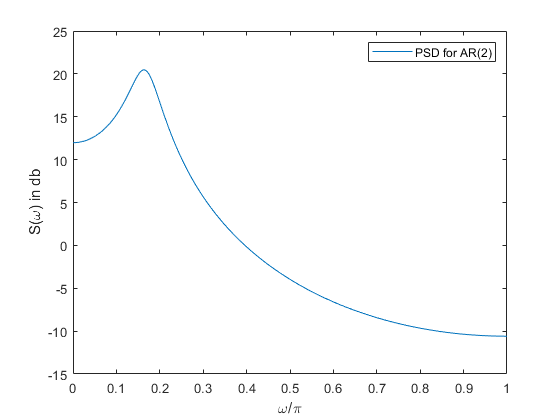

x = randn(N, 1)'; % Random noise with zero mean and unit variance.
b0 = 1;

% Estimate the output signal using the AR(2) model
y_hat = zeros(N, 1);
n = 3:N; % Trick to make it work in MATLAB
y_hat(n) = -(a(1)*y(n-1) + a(2)*y(n-2)) + b0*x(n);

% Plot the two 
n = 1:N;
plot(n, y(n), n, y_hat(n))
legend('Original signal y[n]', 'AR(2) estimated signal y*[n]');
xlabel('Sample number (n)')

ylabel('Signal')

## Exam 2016 Problem 1: AR(p) signal modelling

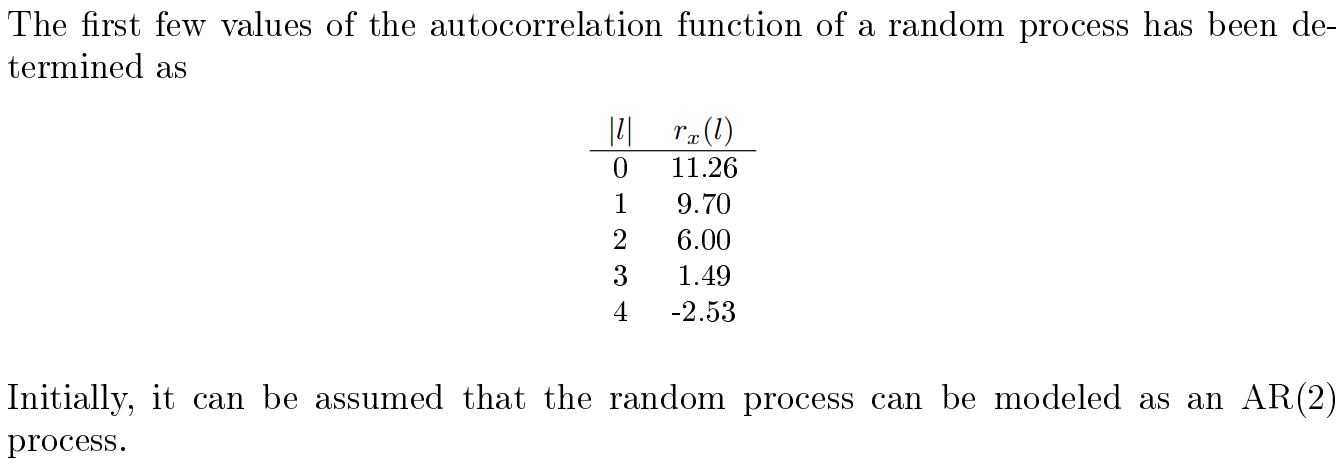

clear variables;

MSE_ar2 = 0.9922

### 1) Compute AR(2) model coefficient given autocorrelation sequence

An AR(p) model is given by:

        
$$y\left(n\right)=-\sum_{k=1}^p \left\lbrack a_k \;y\left(n-k\right)\right\rbrack +b_0 x\left(n\right)$$


The autocorrelation of AR(q) model was derived in Eq. 13.141 as:

        
$$r_{\mathrm{yy}} \left(\ell \right)=-\sum_{k=1}^p a_k r_{\mathrm{yy}} \left(\ell -k\right),\;\;\;\ell >0$$
 

This is useful because we can use it to find the coefficients $\left\lbrace a_k \right\rbrace$ of an AR(q) model using the autocorrelation $r_{\mathrm{yy}} \left(\ell \right)$ computed numerically in MATLAB. This means that the expression in Eq. 13.141 becomes a set of $p$ linear equations.

An AR(2) model is given by:

        
$$y\left(n\right)=-\left(a_1 \;y\left(n-1\right)+a_2 \;y\left(n-2\right)\right)+b_0 x\left(n\right)$$


We can estimate the model parameters of a second-order AR model$p=2$ by creating two equations with two unknowns:

        
$$r_{\mathrm{yy}} \left(1\right)=-a_1 r_{\mathrm{yy}} \left(0\right)-a_2 r_{\mathrm{yy}} \left(-1\right)$$


        
$$r_{\textrm{yy}} \left(2\right)=-a_1 r_{\textrm{yy}} \left(1\right)-a_2 r_{\textrm{yy}} \left(0\right)$$


We can write it into matrix form using the Toeplitz matrix:

        
$$\left\lbrack \begin{array}{cc}
r_{\mathrm{yy}} \left(0\right) & r_{\mathrm{yy}} \left(-1\right)\\
r_{\mathrm{yy}} \left(1\right) & r_{\mathrm{yy}} \left(0\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
a_2 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
r_{\mathrm{yy}} \left(1\right)\\
r_{\mathrm{yy}} \left(2\right)
\end{array}\right\rbrack$$


In the general case, it becomes:

More compactly written as *Yule–Walker equations*:

        

The input noise variance can be compute as follows:

        

This is coded in MATLAB function (see end of document):

p = 2;

MSE_ar3 = 0.9922

r_xx = [11.26, 9.70, 6.00, 1.49, -2.53]';

MSE_ar4 = 0.9919

[a, v] = ar_from_acrs(r_xx, p)

The power spectrum of an ARMA(p, q) process is given by:

        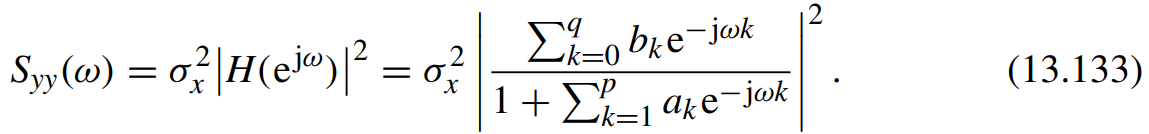

The power spectrum of an AR(p) process is given by:

        
$$S_{\mathrm{yy}} \left(\omega \right)=\sigma_x^2 {\left|\frac{1}{1+\sum_{k=1}^p a_k e^{-j\omega k} }\right|}^2$$


To solve this problem, the method is as follows:

- Find the coefficents $\left\lbrace a_1 ,a_2 ,\cdots ,a_p \right\rbrace$ for the$\mathrm{AR}\left(p\right)$ model

- Compute the transfer function for the $\mathrm{AR}\left(p\right)$ by computing the sum and finding its reciprocal

- Compute the conjugate of the transfer function: ${\left|H\left(e^{j\omega } \right)\right|}^2$

- Multiply it with the variance $\sigma_x^2$

The method above is implemented in the function `ar2psd `(see at the end of document):

[S, w] = ar2psd(a, v, 256);
plot(w/pi, real(pow2db(S)))
legend('PSD for AR(2)')
xlabel('\omega/\pi')
ylabel('S(\omega) in db')

### 2) Is the random process better modelled as an AR(3) or higher-order process?

The variane $\sigma_x^2$ calculated above corresponds to the minimum Mean Squared Error (MSE) for the AR(2) model. So for a higher order model to be a better model the MSE must be lower than for the AR(2) model. 

We can solve the equations for different AR(q) models:

MSE_ar2 = v
[~, MSE_ar3] = ar_from_acrs(r_xx, 3)
[~, MSE_ar4] = ar_from_acrs(r_xx, 4)

The MSE is lowered very slightly when the model order is increased.

Because of the slight change we can be conclude that the process is not better modeled as an AR(3) or AR(4) process.

## Exam 2018 Problem 2: Signal Modelling using MA(2) or AR(2) 

clear variables;

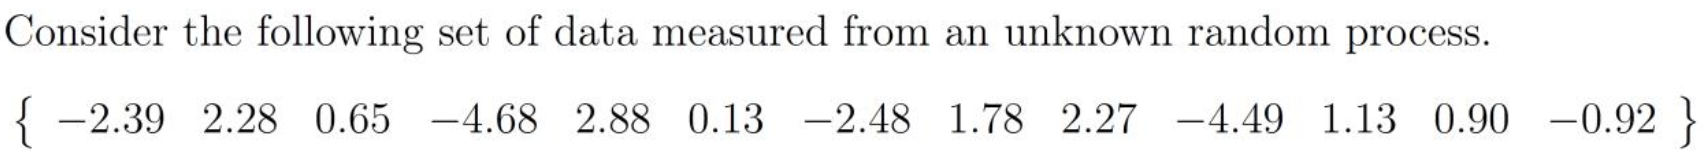

### [✔] 1) Calculate and plot the autocorrelation function of the data

x = [-2.39, 2.28, 0.65, -4.68, 2.88, 0.13, -2.48, 1.78, 2.27, -4.49, 1.13, 0.9, -0.92];

ans =     6.0855   -2.7605   -2.6160    4.1680   -1.0665


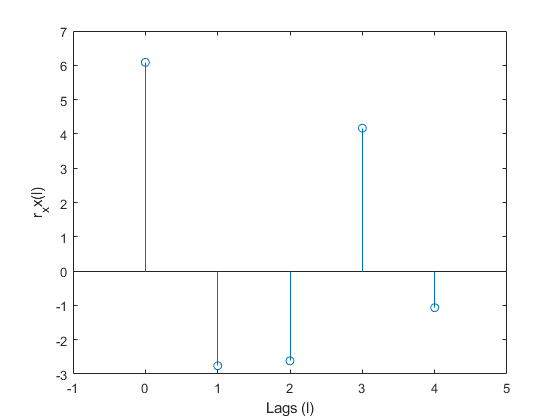


% Estimate autocorrelation using data
[r_xx, ell] = xcorr(x, 'biased');

% Print out the lags 0 to 4

mid = floor(numel(ell)/2)+1;
r_xx(mid:mid+4)
% Plot the results
stem(0:4, r_xx(mid:mid+4))
xlim([-1, 5])
xlabel('Lags (l)')
ylabel('r_xx(l)')

### 2) Can data be described by an MA(2) model?

MA(2) model is given by:

        
$$y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack +b_2 \;x\left\lbrack n-2\right\rbrack$$


where $x\left\lbrack n\right\rbrack ~\mathrm{WN}\left(0,\sigma_x^2 \right)$ 

The autocorrelation for an MA(2) process is:

        
$$r_{\mathrm{yy}} \left(\ell \right)=\left(b_0^2 +b_1^2 +b_2^2 \right)\delta \left(\ell \right)+\left(b_0 b_1 +b_1 b_2 \right)\delta \left(\ell +1\right)+\left(b_0 b_1 +b_1 b_2 \right)\delta \left(\ell -1\right)+b_0 b_2 \delta \left(\ell +2\right)+b_0 b_2 \delta \left(\ell -2\right)$$


Clearly, the autocorrelation for an MA(2) for $\ell >2$ is zero.

The estimated autocorrelation for the data is:

r_xx(mid:mid+4)

ans =     6.0855   -2.7605   -2.6160    4.1680   -1.0665


Since the estimated autocorrelation has non-zero values for $\ell >2$, it cannot be described by an MA(2) model.

### 3) Calculate the power spectral density of the random process assuming an AR(2) model

Before we can compute the PSD, we need to find the AR(2) model coefficients.

An AR(p) model is given by:

        
$$y\left(n\right)=-\sum_{k=1}^p \left\lbrack a_k \;y\left(n-k\right)\right\rbrack +b_0 x\left(n\right)$$


The autocorrelation of AR(q) model was derived in Eq. 13.141 as:

        
$$r_{\mathrm{yy}} \left(\ell \right)=-\sum_{k=1}^p a_k r_{\mathrm{yy}} \left(\ell -k\right),\;\;\;\ell >0$$
 

This is useful because we can use it to find the coefficients $\left\lbrace a_k \right\rbrace$ of an AR(q) model using the autocorrelation $r_{\mathrm{yy}} \left(\ell \right)$ computed numerically in MATLAB. This means that the expression in Eq. 13.141 becomes a set of $p$ linear equations.

An AR(2) model is given by:

        
$$y\left(n\right)=-\left(a_1 \;y\left(n-1\right)+a_2 \;y\left(n-2\right)\right)+b_0 x\left(n\right)$$


We can estimate the model parameters of a second-order AR model$p=2$ by creating two equations with two unknowns:

        
$$r_{\mathrm{yy}} \left(1\right)=-a_1 r_{\mathrm{yy}} \left(0\right)-a_2 r_{\mathrm{yy}} \left(-1\right)$$


        
$$r_{\textrm{yy}} \left(2\right)=-a_1 r_{\textrm{yy}} \left(1\right)-a_2 r_{\textrm{yy}} \left(0\right)$$


We can write it into matrix form using the Toeplitz matrix:

        
$$\left\lbrack \begin{array}{cc}
r_{\mathrm{yy}} \left(0\right) & r_{\mathrm{yy}} \left(-1\right)\\
r_{\mathrm{yy}} \left(1\right) & r_{\mathrm{yy}} \left(0\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
a_2 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
r_{\mathrm{yy}} \left(1\right)\\
r_{\mathrm{yy}} \left(2\right)
\end{array}\right\rbrack$$


In the general case, it becomes:

More compactly written as:

        
$${\mathit{\mathbf{R}}}_y \;\mathit{\mathbf{a}}=-{\mathit{\mathbf{r}}}_y$$


This is a system of linear equations which can be solved in MATLAB using `arfit` function (see bottom of the document).

The power spectrum of an ARMA(p, q) process is given by:

        

The power spectrum of an AR(p) process is given by:

        
$$S_{\mathrm{yy}} \left(\omega \right)=\sigma_x^2 {\left|\frac{1}{1+\sum_{k=1}^p a_k e^{-j\omega k} }\right|}^2$$


To solve this problem, the method is as follows:

- Find the coefficents $\left\lbrace a_1 ,a_2 ,\cdots ,a_p \right\rbrace$ for the$\mathrm{AR}\left(p\right)$ model

- Compute the transfer function for the $\mathrm{AR}\left(p\right)$ by computing the sum and finding its reciprocal

- Compute the conjugate of the transfer function: ${\left|H\left(e^{j\omega } \right)\right|}^2$

- Multiply it with the variance $\sigma_x^2$

The method above is implemented in the functions `arfit()` and `ar2psd():`

[a, v] = arfit(x, 2)

a =     0.8167
    0.8003


v = 1.7374

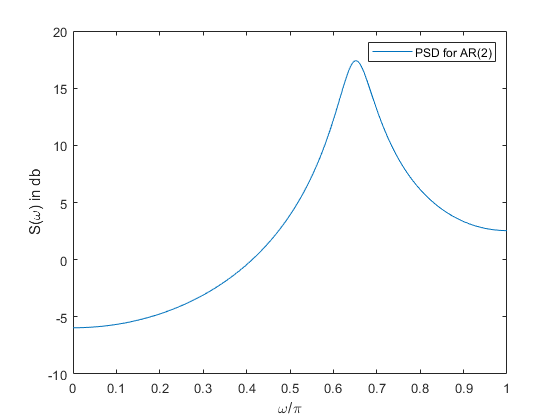

[S, w] = ar2psd(a, v, 256);
plot(w/pi, real(pow2db(S)))
legend('PSD for AR(2)')
xlabel('\omega/\pi')
ylabel('S(\omega) in db')

## Problem 1: Signal modelling assuming AR(2) process

clear variables;

### 1) Compute AR(2) model coefficient given autocorrelation sequence

An AR(p) model is given by:

        
$$y\left(n\right)=-\sum_{k=1}^p \left\lbrack a_k \;y\left(n-k\right)\right\rbrack +b_0 x\left(n\right)$$


The autocorrelation of AR(q) model was derived in Eq. 13.141 as:

        
$$r_{\mathrm{yy}} \left(\ell \right)=-\sum_{k=1}^p a_k r_{\mathrm{yy}} \left(\ell -k\right),\;\;\;\ell >0$$
 

This is useful because we can use it to find the coefficients $\left\lbrace a_k \right\rbrace$ of an AR(q) model using the autocorrelation $r_{\mathrm{yy}} \left(\ell \right)$ computed numerically in MATLAB. This means that the expression in Eq. 13.141 becomes a set of $p$ linear equations.

An AR(2) model is given by:

        
$$y\left(n\right)=-\left(a_1 \;y\left(n-1\right)+a_2 \;y\left(n-2\right)\right)+b_0 x\left(n\right)$$


We can estimate the model parameters of a second-order AR model$p=2$ by creating two equations with two unknowns:

        
$$r_{\mathrm{yy}} \left(1\right)=-a_1 r_{\mathrm{yy}} \left(0\right)-a_2 r_{\mathrm{yy}} \left(-1\right)$$


        
$$r_{\textrm{yy}} \left(2\right)=-a_1 r_{\textrm{yy}} \left(1\right)-a_2 r_{\textrm{yy}} \left(0\right)$$


We can write it into matrix form using the Toeplitz matrix:

        
$$\left\lbrack \begin{array}{cc}
r_{\mathrm{yy}} \left(0\right) & r_{\mathrm{yy}} \left(-1\right)\\
r_{\mathrm{yy}} \left(1\right) & r_{\mathrm{yy}} \left(0\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
a_2 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
r_{\mathrm{yy}} \left(1\right)\\
r_{\mathrm{yy}} \left(2\right)
\end{array}\right\rbrack$$


In the general case, it becomes:

More compactly written as *Yule–Walker equations*:

        

The input noise variance can be compute as follows:

        

This is coded in MATLAB function (see end of document):

p = 2;
r_xx = [11.26, 9.70, 6.00, 1.49, -2.53]';
[a, v] = ar_from_acrs(r_xx, p)

a =    -1.5604
    0.8114


v = 0.9922

The power spectrum of an ARMA(p, q) process is given by:

        

The power spectrum of an AR(p) process is given by:

        
$$S_{\mathrm{yy}} \left(\omega \right)=\sigma_x^2 {\left|\frac{1}{1+\sum_{k=1}^p a_k e^{-j\omega k} }\right|}^2$$


To solve this problem, the method is as follows:

- Find the coefficents $\left\lbrace a_1 ,a_2 ,\cdots ,a_p \right\rbrace$ for the$\mathrm{AR}\left(p\right)$ model

- Compute the transfer function for the $\mathrm{AR}\left(p\right)$ by computing the sum and finding its reciprocal

- Compute the conjugate of the transfer function: ${\left|H\left(e^{j\omega } \right)\right|}^2$

- Multiply it with the variance $\sigma_x^2$

The method above is implemented in the function `ar2psd `(see at the end of document):

[S, w] = ar2psd(a, v, 256);
plot(w/pi, real(pow2db(S)))
legend('PSD for AR(2)')
xlabel('\omega/\pi')
ylabel('S(\omega) in db')

### 2) Is the random process better modelled as an AR(3) or higher-order process?

The variane $\sigma_x^2$ calculated above corresponds to the minimum Mean Squared Error (MSE) for the AR(2) model. So for a higher order model to be a better model the MSE must be lower than for the AR(2) model. 

We can solve the equations for different AR(q) models:

MSE_ar2 = v

MSE_ar2 = 0.9922

[~, MSE_ar3] = ar_from_acrs(r_xx, 3)

MSE_ar3 = 0.9922

[~, MSE_ar4] = ar_from_acrs(r_xx, 4)

MSE_ar4 = 0.9919

The MSE is lowered very slightly when the model order is increased.

Because of the slight change we can be conclude that the process is not better modeled as an AR(3) or AR(4) process.

## Functions

function [S, w] = ar2psd(a, v, N)
% AR2PSD Compute the Power Spectral Density from AR(p) coefficients
%   [S, w] = ar2psd(a, v, N)
% a: AR(p) coefficients
% v: the variance
% N: number of points in the range [1, pi]
% S: the estimated power spectrum
% w: frequencies
    w = linspace(0, 1, N) * pi;
    
    % Compute the transfer function
    % Used Eq. (13.133) in the book
    H = ones(N, 1);
    for k=1:numel(a)
        H = H + a(k)*exp(-1j * w' * k);
    end
    H = 1./H;
    
    % Finally compute the PSD
    S = v * H.*conj(H);
end

function [a,v] = arfit(x,p)
    % fit AR(p) model from data
    % x: data
    % p: model order
    % a: a coefficients
    % v: variance
    if isrow(x)
        x = x'; % Convert to a column vector
    end
    
    % Compute the autocorrelation
    [r_xx, lags] = xcorr(x, p, 'biased');
    
    % Select elements r_xx[0] to r_xx[p-1]
    R_elems = r_xx(p+1:2*p);
    
    % Create the Toeplitz matrix
    R = toeplitz(R_elems);
    
    % Select elements r_xx[1] to r_xx[p]
    r = r_xx(p+2:2*p+1);
    
    % Solve systems of linear equations using mldivide function
    a = mldivide(R, -r);
    
    % Compute the variance
    v = r_xx(p+1) + a'*r;
end


function [a, v] = ar_from_acrs(r_xx, p)
    R_xx = toeplitz(r_xx(1:p));
    
    % Select elements r_xx[1] to r_xx[p]
    r = r_xx(2:p+1);
    
    % Solve Yule-Walker equation (13.143)
    a = mldivide(R_xx, -r);
    
    % Compute the variance according to Eq. (13.144)
    v = r_xx(1) + a'*r;
end
